# Circuit Demo

The purpose of this file is to demonstrate Laplace domain matching of cascaded S-parameters. Two circuits are created, fit with a rational function, and then are cascaded into a two port network which can optimized for.

## Create the first circuit

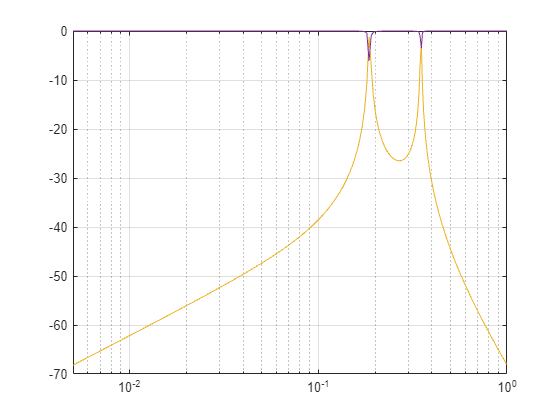

cir1 = circuit('Circuit1');
nelem = 6;
stx = rand(1, nelem);
add(cir1, [1, 2], inductor(stx(1)));
add(cir1, [1, 3], capacitor(stx(2)));
add(cir1, [2, 4], capacitor(stx(3)));
add(cir1, [3, 4], inductor(stx(4)));
add(cir1, [1, 3], inductor(stx(5)));
add(cir1, [2, 4], inductor(stx(6)));
setports(cir1, [1, 3], [2, 4]);

freqs = linspace(0, 1, 200);
s1 = sparameters(cir1, freqs);
plot(freqs, db(squeeze(s1.Parameters(1,1,:))), freqs, db(squeeze(s1.Parameters(1,2,:))), ...
    freqs, db(squeeze(s1.Parameters(2,1,:))), freqs, db(squeeze(s1.Parameters(2,2,:)))); xscale('log'); grid on;